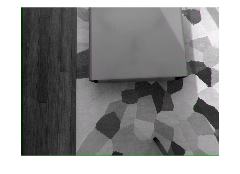

%% Загрузка изображений
folderPath = 'Resources/';
files = dir(fullfile(folderPath,'*.png'));

% Подготовка массива для хранения изображений
numImages = numel(files);
imageArray = cell(1, numImages);

% Загрузка изображений в массив
for i = 1:numImages
    imagePath = fullfile(folderPath, files(i).name);
    imageArray{i} = imread(imagePath);
end
%% Обработка изображений
xy_shifts = zeros(9,2); % Массив для хранения сдвигов
for i = 1:(numImages-1) % Цикл для обработки всех пар изображений
    xy_shifts(i,:) = (find_shift_xy(imageArray{i},imageArray{i + 1}));
end

disp(xy_shifts) % вывод сдвигов на экран

     8    -2
    12    -3
     8    -3
     9    -2
    10    -1
     8    -1
     8    -3
     9    -1
     8    -4



function shift = find_shift_xy(image1,image2)
shape  = size(image1);
%% Преобразование Фурье изображений
f_image1 = fftn(image2);
f_image2 = fftn(image1);
%f_image2*f_image1
%eps = eps();
%% Вычисление 
%остановка тут
C = f_image1 .* conj(f_image2);
C = C ./max(abs(C()),eps * 100);
%MAxx = max(abs(C()),eps() * 100);
%Maxx = eps * 100
%m = max(abs(C(:)));
%C = C./abs(C)
%C = C/MAxx;
%cov = (ifft(f_image1 .* conj(f_image2)));
cov = (ifft2(C));
surf(abs(cov));
shading flat;
mxm=max(abs(cov(:))); % определение максимального элемента
abs(cov(766,8));
[max_row,max_col] =find(abs(cov)==mxm); % определение строки и столбца с максимальным элементом
center = [fix(shape(1)/2),fix(shape(2)/2)];
shift = [max_row,max_col];
shift(shift > center) = shift(shift > center) - shape(shift > center);
shift(:) = shift - 1;
shift = fliplr(shift);
imshowpair(image2,imtranslate(image1,shift),'falsecolor')
end